%----------------------------------------------------------------------
%Name : Sumit Patidar
%Roll no: B15237
%Task : program to compare linear and circular convolution
%----------------------------------------------------------------------

close all;
clear all;
clc;

filename = ('/Users/sumitpatidar/Desktop/sample_audio_2.m4a');
%read a audio file
[y, Fs] = audioread(filename);
N = Fs;
samples = [1, N];
[y1, Fs] = audioread(filename , samples);

filename_in = '/Users/sumitpatidar/Desktop/audio_in2.wav'

filename_in = '/Users/sumitpatidar/Desktop/audio_in2.wav'

audiowrite(filename_in, y1, Fs);
%sound(y1, N);

%DFT of the input sound signal
X_in = dft_user(y1, N);

%plot DFT of input signal
p1 = subplot(3,1,1);
stem([0:N-1], abs(X_in));
xlabel('number of samples(n)');
ylabel('amplitute');
title('DFT X[k]');
hold on;

%----------------------------------------Low pass filtering begin-------------------------
%DFT of low pass filter signal
n = 0:1:N-1;
wc = pi/2;
X_lp = zeros(1, N);
for k = 0:N-1
    if ((2*pi*k/N) >= wc && ((2*pi*k/N)) <= (2*pi - wc))
        X_lp(k+1) = 0;
    else 
        X_lp(k+1) = 1;
    end
end

%multiply the two signals
Y_lp = X_lp.*X_in;

%plot DFT of input signal
p2 = subplot(3,1,2);
stem([0:N-1], abs(X_lp));
xlabel('number of samples(n)');
ylabel('amplitute');
title('DFT X_{lp}[k]');
hold on;

%plot DFT of input signal
p3 = subplot(3,1,3);
stem([0:N-1], abs(Y_lp));
xlabel('number of samples(n)');
ylabel('amplitute');
title('DFT Y_{lp} [k]');
hold on;

%take idft to convert it back to time domain
y_out = idft_user(Y_lp, N);
y_lp = abs(y_out);

filename_out = '/Users/sumitpatidar/Desktop/audio_lp2.wav'

filename_out = '/Users/sumitpatidar/Desktop/audio_lp2.wav'

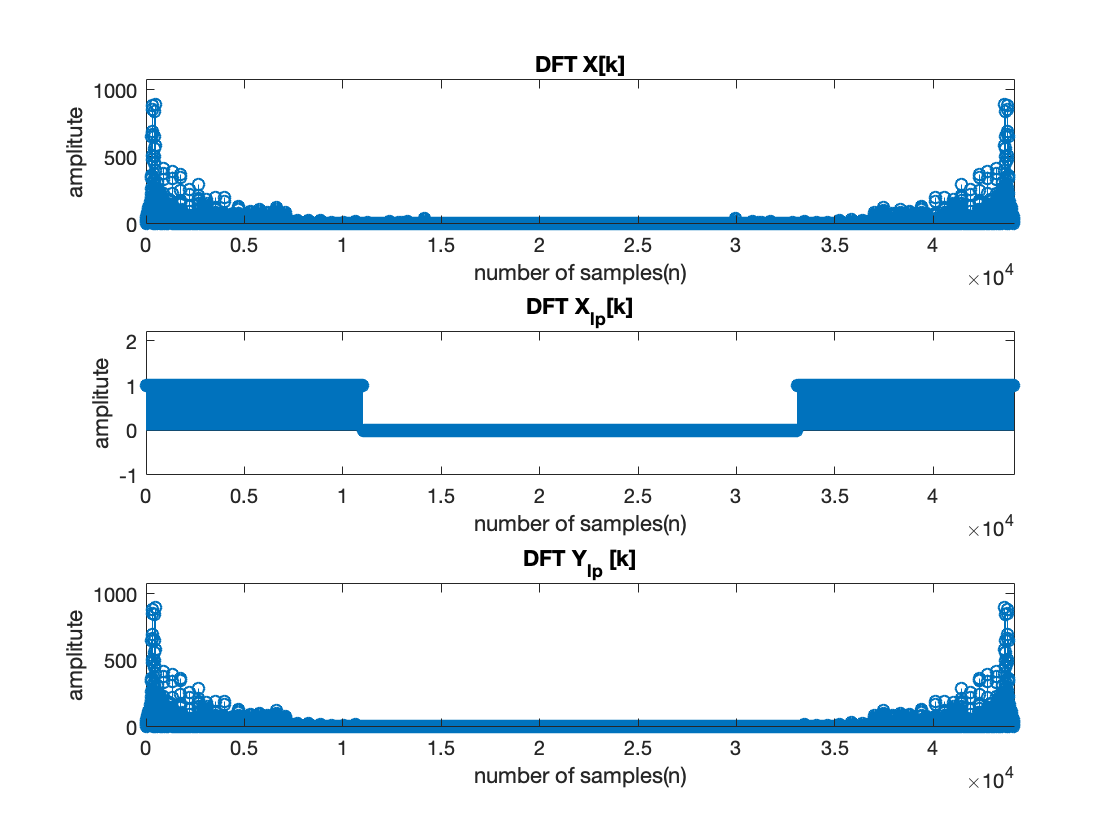

audiowrite(filename_out, y_lp, Fs);
%sound(y_lp, Fs);
%----------------------------------------Low pass filtering end-------------------------

%setting axis limits to visualize better
axis(p1, [-1  N min(abs(X_in))*1.2-1 max(abs(X_in))*1.2+1]);
axis(p2, [-1  N min(abs(X_lp))*1.2-1 max(abs(X_lp))*1.2+1]);
axis(p3, [-1  N min(abs(Y_lp))*1.2-1 max(abs(Y_lp))*1.2+1]);